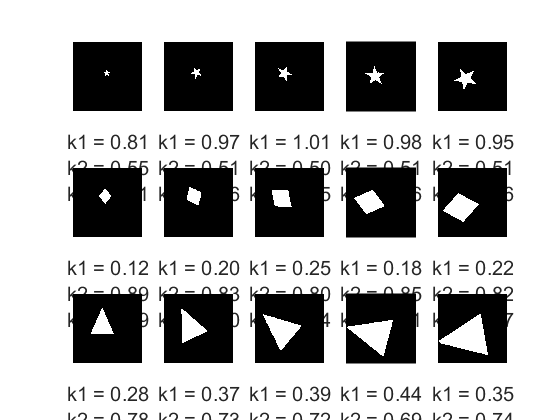

clear all
clc
close all


I=imbinarize(rgb2gray(imread("gwiazda.png")));
[a,b]=size(I);

x_width=16; y_width=10;
font_size = 15;
zad1=figure;

j=0;
k=0.5;
j_sub=0;
 sc= int8(-10 + 10.*rand(5,2));
    for i=1:25:116
        j=j+1;
        J = imresize(I,k);
        k=k+0.25;
        Ramka=length(J)-((length(J)/2)+256);
         if(Ramka>=0)
            img=J(Ramka+1:(length(J)-Ramka),Ramka+1:(length(J)-Ramka));
         else
           img=uint8(zeros(a,b));
           Ramka=-Ramka;
           img(Ramka+1:(length(I)-Ramka),Ramka+1:(length(I)-Ramka))=J;
         end
        Ir=imrotate(img,i-1,'crop');
        It=imtranslate(Ir,sc(j,:));
        
       [Mz, M, K] = wsk(It);
      
        j_sub= j_sub+1;
        subplot(3,5,j_sub)
        imshow(It,[])
        xlabel({['k1 = ',num2str(M,'%.2f')]; ...
        ['k2 = ',num2str(Mz,'%.2f')]; ...
        ['k3 = ',num2str(K,'%.2f')]}, ...
        'fontSize',font_size);
    end
   
I=imbinarize(rgb2gray(imread("romb.png")));

j=0;
k=0.75;
  sc= int8(-10 + 10.*rand(5,2));
    for i=1:25:116
        j=j+1;
        J = imresize(I,k);
        k=k+0.25;
        Ramka=length(J)-((length(J)/2)+256);
         if(Ramka>=0)
            img=J(Ramka+1:(length(J)-Ramka),Ramka+1:(length(J)-Ramka));
         else
           img=uint8(zeros(a,b));
           Ramka=-Ramka;
           img(Ramka+1:(length(I)-Ramka),Ramka+1:(length(I)-Ramka))=J;
         end
        Ir=imrotate(img,i-1,'crop');
        It=imtranslate(Ir,sc(j,:));
        
        [Mz, M, K] = wsk(It);
      
        j_sub= j_sub+1;
        subplot(3,5,j_sub)
        imshow(It,[])
        xlabel({['k1 = ',num2str(M,'%.2f')]; ...
        ['k2 = ',num2str(Mz,'%.2f')]; ...
        ['k3 = ',num2str(K,'%.2f')]}, ...
        'fontSize',font_size);
    end


I=imbinarize(rgb2gray(imread("trojkat.png")));


j=0;
k=1.25;
 sc= int8(-10 + 10.*rand(5,2));
    for i=1:25:116
        j=j+1;
        J = imresize(I,k);
        k=k+0.25;
        Ramka=length(J)-((length(J)/2)+256);
         if(Ramka>=0)
            img=J(Ramka+1:(length(J)-Ramka),Ramka+1:(length(J)-Ramka));
         else
           img=uint8(zeros(a,b));
           Ramka=-Ramka;
           img(Ramka+1:(length(I)-Ramka),Ramka+1:(length(I)-Ramka))=J;
         end
        Ir=imrotate(img,i-1,'crop');
        It=imtranslate(Ir,sc(j,:));
      
       [Mz, M, K] = wsk(It);
      
        j_sub= j_sub+1;
        subplot(3,5,j_sub)
        imshow(It,[])
        xlabel({['k1 = ',num2str(M,'%.2f')]; ...
        ['k2 = ',num2str(Mz,'%.2f')]; ...
        ['k3 = ',num2str(K,'%.2f')]}, ...
        'fontSize',font_size);
    end

    
    set(gcf, 'PaperUnits', 'inches');
    set(gcf, 'PaperPosition', [0 0 x_width y_width]); 
    

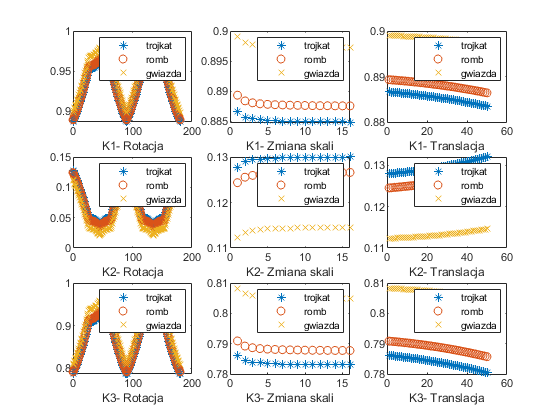

    
clear all
clc
close all


I1=imread("trojkat.png");
I1=rgb2gray(I1);
O1op=graythresh(I1)*255;
I1=logical(binarka(I1,O1op));

I2=imread("romb.png");
I2=rgb2gray(I2);
O2op=graythresh(I2)*255;
I2=logical(binarka(I2,O2op));

I3=imread("gwiazda.png");
I3=rgb2gray(I3);
O3op=graythresh(I3)*255;
I3=logical(binarka(I3,O3op));

x_width=16; y_width=10;
font_size = 15;
zad2=figure;


    for i=1:1:181
      
        I1r=imrotate(I1,i-1,'crop');
        [Mz, M, K] = wsk(I1r);
        TAB_WSK_1(1,i)=Mz;
        TAB_WSK_2(1,i)=M;
        TAB_WSK_3(1,i)=K;
        
        I2r=imrotate(I2,i-1,'crop');
        [Mz, M, K] = wsk(I2r);
        TAB_WSK_1(2,i)=Mz;
        TAB_WSK_2(2,i)=M;
        TAB_WSK_3(2,i)=K;
        
        I3r=imrotate(I3,i-1,'crop');
        [Mz, M, K] = wsk(I3r);
        TAB_WSK_1(3,i)=Mz;
        TAB_WSK_2(3,i)=M;
        TAB_WSK_3(3,i)=K;
      
    end
        
         subplot(3,3,1)
        plot(0:180,TAB_WSK_1(1,:),'*')
        hold on
        plot(0:180,TAB_WSK_1(2,:),'o')
        hold on
        plot(0:180,TAB_WSK_1(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K1- Rotacja')
          subplot(3,3,4)
        plot(0:180,TAB_WSK_2(1,:),'*')
        hold on
        plot(0:180,TAB_WSK_2(2,:),'o')
        hold on
        plot(0:180,TAB_WSK_2(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K2- Rotacja')
          subplot(3,3,7)
        plot(0:180,TAB_WSK_3(1,:),'*')
        hold on
        plot(0:180,TAB_WSK_3(2,:),'o')
        hold on
        plot(0:180,TAB_WSK_3(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K3- Rotacja')
        TAB_WSK_1=[];
        TAB_WSK_2=[];
        TAB_WSK_3=[];

    for i=1:1:50
      
        I1t=imtranslate(I1,[i,0]);
        [Mz, M, K] = wsk(I1t);
        TAB_WSK_1(1,i)=Mz;
        TAB_WSK_2(1,i)=M;
        TAB_WSK_3(1,i)=K;
        
        I2t=imtranslate(I2,[i,0]);
        [Mz, M, K] = wsk(I2t);
        TAB_WSK_1(2,i)=Mz;
        TAB_WSK_2(2,i)=M;
        TAB_WSK_3(2,i)=K;
        
        I3t=imtranslate(I3,[i,0]);
        [Mz, M, K] = wsk(I3t);
        TAB_WSK_1(3,i)=Mz;
        TAB_WSK_2(3,i)=M;
        TAB_WSK_3(3,i)=K;
      
    end
        
         subplot(3,3,3)
        plot(1:50,TAB_WSK_1(1,:),'*')
        hold on
        plot(1:50,TAB_WSK_1(2,:),'o')
        hold on
        plot(1:50,TAB_WSK_1(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K1- Translacja')
          subplot(3,3,6)
        plot(1:50,TAB_WSK_2(1,:),'*')
        hold on
        plot(1:50,TAB_WSK_2(2,:),'o')
        hold on
        plot(1:50,TAB_WSK_2(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K2- Translacja')
          subplot(3,3,9)
        plot(1:50,TAB_WSK_3(1,:),'*')
        hold on
        plot(1:50,TAB_WSK_3(2,:),'o')
        hold on
        plot(1:50,TAB_WSK_3(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K3- Translacja')
    TAB_WSK_1=[];
        TAB_WSK_2=[];
        TAB_WSK_3=[];

    for i=1:1:16
      
        J1 = imresize(I1,i);
        [Mz, M, K] = wsk(J1);
        TAB_WSK_1(1,i)=Mz;
        TAB_WSK_2(1,i)=M;
        TAB_WSK_3(1,i)=K;
        
        J2 = imresize(I2,i);
        [Mz, M, K] = wsk(J2);
        TAB_WSK_1(2,i)=Mz;
        TAB_WSK_2(2,i)=M;
        TAB_WSK_3(2,i)=K;
        
        J3 = imresize(I3,i);
        [Mz, M, K] = wsk(J3);
        TAB_WSK_1(3,i)=Mz;
        TAB_WSK_2(3,i)=M;
        TAB_WSK_3(3,i)=K;
      
    end
        
         subplot(3,3,2)
        plot(1:16,TAB_WSK_1(1,:),'*')
        hold on
        plot(1:16,TAB_WSK_1(2,:),'o')
        hold on
        plot(1:16,TAB_WSK_1(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K1- Zmiana skali')
        
          subplot(3,3,5)
        plot(1:16,TAB_WSK_2(1,:),'*')
        hold on
        plot(1:16,TAB_WSK_2(2,:),'o')
        hold on
        plot(1:16,TAB_WSK_2(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K2- Zmiana skali')
        
        
          subplot(3,3,8)
        plot(1:16,TAB_WSK_3(1,:),'*')
        hold on
        plot(1:16,TAB_WSK_3(2,:),'o')
        hold on
        plot(1:16,TAB_WSK_3(3,:),'x')
        legend("trojkat","romb","gwiazda");
        xlabel('K3- Zmiana skali')

        

    set(gcf, 'PaperUnits', 'inches');
    set(gcf, 'PaperPosition', [0 0 x_width y_width]); 
    